Data Science (Prof. Neff)                    Abgabedatum 15.12.2020

Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),

                    Anna Kuhn (2051063), Michael Schulze (2061282)

# Labor zur Prozesskontrolle 

clear

## 1) Auswahl des Prozesses

Übertragungsgeschwindigkeit USB2.0 Stick

Gemessen mit CrystalDiskMark , 10mal von jedem Gruppenteilnehmer (1x 1GiB Zufallsdaten Read SEQ1M Q8T1 in MB/s)

Toleranz sollte eigentlich von der Spezifikation vorgegeben werden, aber ma kann nicht die Spezifikation vo USB2.0 nehmen, da es theoretische Werte sind und diese abhängig vom verwendeten Rechner und des verbauten USB-Chips sind. Wir haben uns auf eine untere Spezifikation von 16 MB/s festgelegt. Die obere Spezifikation kann theoretisch weggelassen werden, da man bei der Übertragungsgeschwindigkeit in unserem Fall natürlich so schnell wie möglich sein will. Der USB2.0 Standard gibt eine maximale Nutzdatenrate von 40 MB/s an. Diese verwenden wir nun in unseren Berechnungen.

%Spezifikationsgrenzen
specLow = 16

specLow = 16

specHigh = 40

specHigh = 40

## 2) Datensätze auf Normalverteilung prüfen

%Daten einlesen
data=readtable('USB.xlsx')

data = 10×5 table
    Var1    Anna     Benni     Michael     Jan 
    ____    _____    ______    _______    _____

      1     19.71    17.995    17.387     18.45
      2     19.92     18.41     16.96     18.88
      3      19.5     18.73    17.639     18.88
      4      19.5     18.42    16.648     18.88
      5     20.34     18.31    18.541     18.87
      6      19.5     18.31    18.024     18.66
      7     19.71    18.515    18.553     18.87
      8      19.5     18.12    17.675     19.08
      9     19.51    17.885    18.169     19.08
     10      19.5    17.575    16.747     19.09



%

sigma_Anna = 0.2758

variance_Anna = 0.0761

mean_daten_Anna = 19.6690

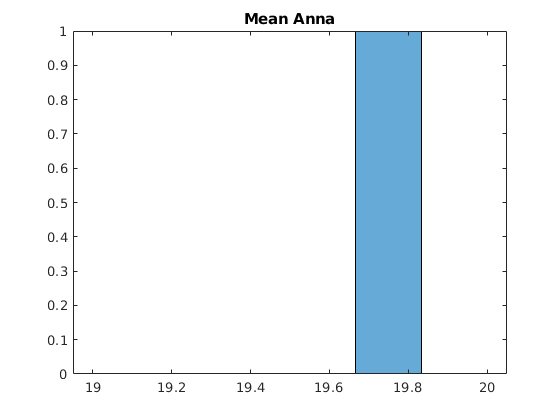

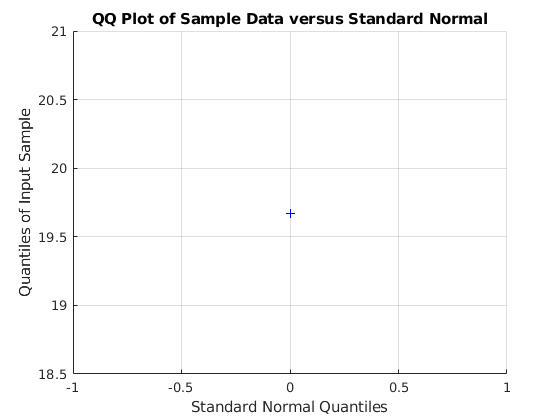

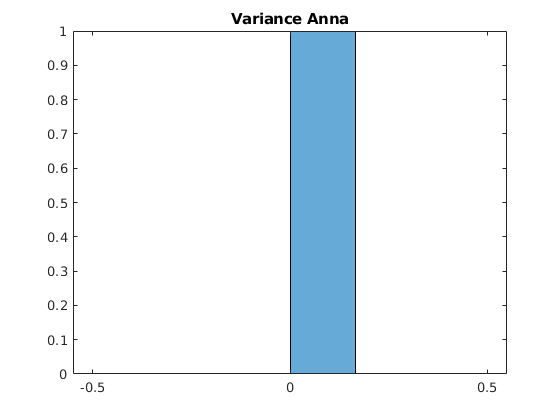

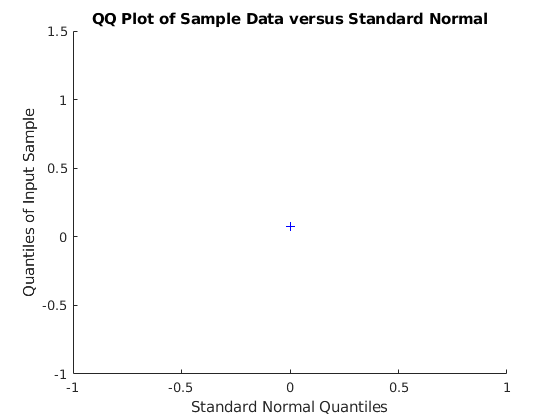

%qq-Plot


## 3) Prozesskennzahlen c_p und c_pk

Ist der Prozess für die Anwendung ausreichend fähig?

## 4a) Regelkarte mit einem Datensatz

Eingriffsgrenzen ermitteln

## 4b) Regelkarten für andere Datensätze mit Eingriffsgrenze aus 4a

Bieten Regelkarten zusätzliche Informationen? Z. B. hat ein Datensatz eine größere Streuung?

Halten Sie die Regelkarte für diese Prozess für nützlich?

## 5) Mittelwerte der Datensätze anhand einer Varianzanalyse vergleichen

# ----- Ab hier unser Code, wie es bisher war -----

%Regelkarten für eine für USB-Geschwindigkeit, Toleranz
%16 bis 30
data=readtable('USB.xlsx')



%Verschiedene Regelkarten
%igure(2)
%Einzelwertkarte
specLow = 16
specHigh = 30
%[stats_i2,plot_i2]=controlchart(data(:,2:5).Variables,data.Var1,'charttype','i','specs',[specLow specHigh])
grid on
[stats_i2,plot_i2]=controlchart(data(:,2:2).Variables,data.Var1,'charttype','i','specs',[specLow specHigh])
[stats_i2,plot_i2]=controlchart(data(:,3:3).Variables,data.Var1,'charttype','i','specs',[specLow specHigh])
[stats_i2,plot_i2]=controlchart(data(:,4:4).Variables,data.Var1,'charttype','i','specs',[specLow specHigh])
[stats_i2,plot_i2]=controlchart(data(:,5:5).Variables,data.Var1,'charttype','i','specs',[specLow specHigh])

%data2
%[stats_i2,plot_i2]=controlchart(data2(:,2:11).Variables,data2.Var1,'charttype','i','specs',[specLow specHigh])

cp_Anna=capability(data(:,2).Variables,[specLow specHigh])
cp_Benni=capability(data(:,3).Variables,[specLow specHigh])
cp_Michael=capability(data(:,4).Variables,[specLow specHigh])
cp_Jan=capability(data(:,5).Variables,[specLow specHigh])

std_Anna = std(data.Anna)
std_Benni = std(data.Benni)
std_Michael = std(data.Michael)
std_Jan = std(data.Jan)

% cpk = 0.4(Anna), 0.2(Benni), -0.1(Michael), 1.4(Jan). 
% Alle Prozesse sind beherrscht (Da innerhalb von UCL und OCL).
% In Halbleiterindustrie muss cpk >= 1,3 sein.
% Nur Jans Prozess ist für die HLI fähig.


%XBAR-Chart mit s und R 
[stats_xs,plot_xs]=controlchart(data(:,2:5).Variables,data.Var1,'charttype',{'xbar' 's'})
% aus XBAR s kann man erkennen, zu welchem Zeitpunkt die größte Streuung
% war
grid on
axes=gca;
axes.XTickLabelRotation=45;

[stats_xr,plot_xr]=controlchart(data(:,2:5).Variables,data.Var1,'charttype',{'xbar' 'r'})
grid on
axes=gca;
axes.XTickLabelRotation=45;

%Darstellung Histogramme und qq-Plots zu Mean und sigma bzw. Varianz, Test
%auf Normalverteilung
sigma=std(data(:,2:5).Variables')

sigma =     0.9845    1.2293    0.7742    1.2254    0.9126    0.6396    0.5553    0.8419    0.7617    1.2885


variance=var(data(:,2:5).Variables')

variance =     0.9693    1.5111    0.5995    1.5015    0.8328    0.4091    0.3084    0.7088    0.5802    1.6603


mean_daten=mean(data(:,2:5).Variables')

mean_daten =    18.3855   18.5425   18.6872   18.3620   19.0153   18.6235   18.9120   18.5938   18.6610   18.2280


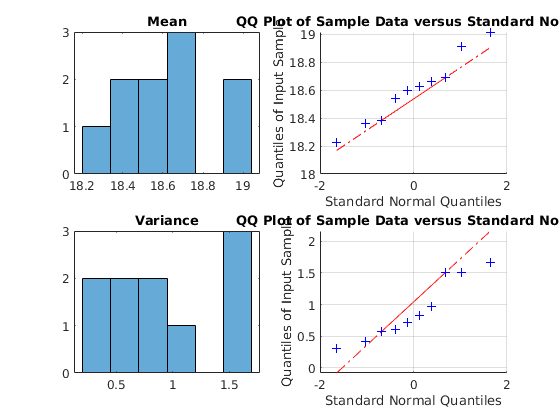

subplot(2,2,1)
histogram(mean_daten,round(2*sqrt(10),0))
title('Mean')
subplot(2,2,2)
qqplot(mean_daten)
grid on
subplot(2,2,3)
histogram(variance,round(2*sqrt(10),0))
title('Variance')
%histogram(sqrt(variance),round(2*sqrt(21),0))
%title('sigma')
subplot(2,2,4)
qqplot(variance)
grid on


[h_mean,p_mean]=adtest(mean_daten)

h_mean = logical
   0


p_mean = 0.8092

[h_var,p_var]=adtest(variance)

h_var = logical
   0


p_var = 0.2044


% Anderson Darlington Test sagt, dass H0 angenommen wird und somit Daten
% normalverteilt sind


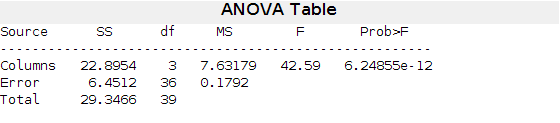

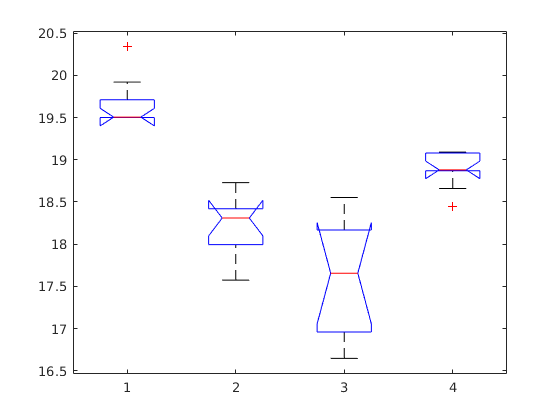

p = 6.2486e-12

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[22.8954]}    {[ 3]}    {[  7.6318]}    {[ 42.5879]}    {[6.2486e-12]}
    {'Error'  }    {[ 6.4512]}    {[36]}    {[  0.1792]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[29.3466]}    {[39]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: [4×1 char]
         n: [10 10 10 10]
    source: 'anova1'
     means: [19.6690 18.2270 17.6343 18.8740]
        df: 36
         s: 0.4233


%ANOVA nur machen, wenn Normalverteilt
[p,tbl,stats] = anova1(data(:,2:5).Variables)

%Mittelwerte sind nicht gleich zwischen den Messreihen


sigsum = sum(sigma)

sigsum = 9.2130

cell2mat(tbl(2,2)) / sigsum

ans = 2.4851

% > 1 -> H0 ablehnen
